# With real MCS LDPC code rate

clear

% Select modulation and coding scheme
modulation = '256QAM'; % Change to '256QAM' for 256-QAM
mcsType = 'moderate'; % Options: 'conservative', 'moderate', 'aggressive'

% Set parameters based on modulation and MCS type
if strcmp(modulation, '64QAM')
    bitsPerSym = 6;
    modOrder = 2^bitsPerSym;
    
    switch mcsType
        case 'conservative'
            coderate = 517/1024; % MCS 19
            BG = 2; % Rate = 0.505 < 2/3
            K = 10 * 384; % 3,840 bits for BG2
        case 'moderate'
            coderate = 616/1024; % MCS 21
            BG = 2; % Rate = 0.602 < 2/3
            K = 10 * 384; % 3,840 bits for BG2
        case 'aggressive'
            coderate = 772/1024; % MCS 24
            BG = 1; % Rate = 0.754 > 2/3
            K = 22 * 384; % 8,448 bits for BG1
    end
else % 256QAM
    bitsPerSym = 8;
    modOrder = 2^bitsPerSym;
    
    switch mcsType
        case 'conservative'
            coderate = 682.5/1024; % MCS 20
            BG = 1; % Rate = 0.667 ≈ 2/3
            K = 22 * 384; % 8,448 bits for BG1
        case 'moderate'
            coderate = 754/1024; % MCS 22
            BG = 1; % Rate = 0.736 > 2/3
            K = 22 * 384; % 8,448 bits for BG1
        case 'aggressive'
            coderate = 885/1024; % MCS 25
            BG = 1; % Rate = 0.864 > 2/3
            K = 22 * 384; % 8,448 bits for BG1
    end
end

% Calculate the lifting size
if BG == 1
    lifting_size = round(K / 22);
else
    lifting_size = round(K / 10);
end

% Verify lifting size is within valid range
if lifting_size < 2 || lifting_size > 384
    error('Invalid lifting size. Must be between 2 and 384');
end

% Calculate encoded length
N = round(K / coderate);

% Verify encoded length is valid for selected Base Graph
if BG == 1
    max_N = 68 * 384;
else
    max_N = 52 * 384;
end

if N > max_N
    error('Encoded length exceeds maximum allowed for selected Base Graph');
end

% LDPC parameters (5G NR)
maxNumIter = 64; % Maximum number of decoding iterations

% Interleaver parameters
interleaverSize = N; % Size of the interleaver (same as codeword length)

% SNR range
SNRdB = (0:0.3:20)';
numSNR = length(SNRdB);

% Methods to test
advType = {'no adv', 'minimax', 'fix flip', 'minimax', 'fix flip'};
llrClip = [false, true, true, false, false]; 
numMeth = length(advType);

% Create method strings
methStr = cell(numMeth,1);
for imeth = 1:numMeth
    if llrClip(imeth)
        clipStr = "clip";
    else
        clipStr = "no clip";
    end
    methStr{imeth} = sprintf('%s+%s', advType{imeth}, clipStr);
    fprintf(1, 'Method %d: %s\n', imeth, methStr{imeth});
end

Method 1: no adv+no clip
Method 2: minimax+clip
Method 3: fix flip+clip
Method 4: minimax+no clip
Method 5: fix flip+no clip



% Simulation parameters
numTrials = 2000;
flipProb = 0.01; % Flip probability to test

% Initialize arrays
BER = zeros(numTrials, numSNR, numMeth);
BLER = zeros(numSNR, numMeth);
flipped = zeros(numTrials, numSNR, numMeth);
llrThresh = zeros(numSNR,1);

BERavg = zeros(numSNR, numMeth);
BLERavg = zeros(numSNR, numMeth);
flipavg = zeros(numSNR, numMeth);
methDone = zeros(numMeth,1);

% Calibrate the threshold for the flip probability
nsym = 1e4;
numBits = nsym * bitsPerSym;
llrThreshTest = linspace(0,10,100)';
nthresh = length(llrThreshTest);

% Generate random bits
bits = randi([0 1], numBits, 1);

% QAM modulate
s = qammod(bits, modOrder, 'InputType', 'bit', 'UnitAveragePower', true);

flipProbTest = zeros(nthresh, numSNR);
capFlip = zeros(nthresh, numSNR);
capNoFlip = zeros(numSNR, 1);

% Calibration loop
for isnr = 1:numSNR
    % Add noise
    snr = SNRdB(isnr);
    noiseVar = db2pow(-snr);
    w = (randn(nsym,1) + 1i*randn(nsym,1))/sqrt(2);
    r = s + db2mag(-snr)*w;

    % Get the LLRs
    z0 = qamdemod(r, modOrder, 'OutputType', 'approxllr', ...
        'UnitAveragePower', true, 'NoiseVariance', noiseVar);

    % Find the accuracy
    z0b = -z0.*(2*bits-1);
    bce = mean(log2(1 + exp(-z0b)));
    capNoFlip(isnr) = 1 - bce;
    
    % Find the flip probability
    for it = 1:nthresh
        % Compute flip prob
        t = llrThreshTest(it);
        p = max(0, (1 - exp(t - z0b)) ./ (1 + exp(t)));
        flipProbTest(it,isnr) = mean(p);
    
        % Flip bits
        u = (rand(numBits,1) < p);
        z0bFlip = -z0b.*(2*u-1);
        
        % Compute capacity 
        bceFlip = mean(log2(1 + exp(-z0bFlip)));
        capFlip(it, isnr) = max(0, 1 - bceFlip);
    end
end

% Find the LLR threshold via interpolation
for isnr = 1:numSNR
    x = flipud(flipProbTest(:,isnr));
    
    % Ensure monotonicity
    for i = 1:nthresh-1
        if x(i+1) < x(i)
            x(i+1) = x(i);
        end
    end
    
    y = flipud(llrThreshTest);
    [x, uniqueIdx] = unique(x, 'stable');
    y = y(uniqueIdx);
    
    % Interpolate to find threshold
    t = interp1(x, y, flipProb);
    llrThresh(isnr) = t;
end

disp('Selected Configuration')

Selected Configuration


disp('======================')

fprintf('▶ Base Graph: %d\n', BG)

▶ Base Graph: 1


fprintf('▶ Information block size (K): %d bits\n', K)

▶ Information block size (K): 8448 bits


fprintf('▶ Encoded block size (N): %d bits\n', N)

▶ Encoded block size (N): 11473 bits


fprintf('▶ Code rate: %.3f\n', coderate)

▶ Code rate: 0.736


fprintf('▶ Lifting size: %d\n', lifting_size)

▶ Lifting size: 384


## Main simulation loop


tic
for isnr = 1:numSNR
    snr = SNRdB(isnr);

    % Find the LLR threshold via interpolation
    x = flipud(flipProbTest(:,isnr));

    for i = 1:nthresh-1
        if x(i+1) < x(i)
            x(i+1) = x(i);
        end
    end
    
    y = flipud(llrThreshTest);
    [x, uniqueIdx] = unique(x, 'stable');
    y = y(uniqueIdx); 
    
    t = interp1(x, y, flipProb);
    llrThresh(isnr) = t;
    tfix = 5*t;

    nerr = zeros(numMeth,numTrials);
    nerr_total = zeros(1,numMeth);

    
    % Parallel processing for trials
    parfor it = 1:numTrials
        % Generate random bits
        bits = randi([0 1], K, 1);
        encodedDataBits = nrLDPCEncode(bits, BG);

        % Interleaving
        interleavedBits = randintrlv(encodedDataBits, it);

        % QAM Modulation
        s = qammod(interleavedBits, modOrder, 'InputType', 'bit', 'UnitAveragePower', true);
        
        % Add AWGN noise
        nsym = length(s);
        noise = (randn(nsym,1) + 1i*randn(nsym,1)) / sqrt(2);
        r = s + db2mag(-SNRdB(isnr)) * noise;
        
        % LLR Calculation
        noiseVar = db2pow(-SNRdB(isnr));
        z0 = qamdemod(r, modOrder, 'OutputType', 'approxllr', ...
            'UnitAveragePower', true, 'NoiseVariance', noiseVar);
        
        % Compute reliability
        z0b = -z0.*(2*interleavedBits-1);
        numBits = length(z0b);

        % Loop over decoding methods
        for imeth = 1:numMeth
            if methDone(imeth)
                continue
            end

            % Apply different adversarial methods
            if strcmp(advType{imeth}, 'no adv')
                z1 = z0;
            elseif strcmp(advType{imeth}, 'minimax')
                p = max(0, (1 - exp(t - z0b)) ./ (1 + exp(t)));
                u = (rand(numBits,1) < p);
                z1 = -z0.*(2*u-1);
            elseif strcmp(advType{imeth}, 'fix flip')
                [zsort, I] = sort(z0b, 'descend');
                nflip = round(numBits*flipProb);
                z1 = z0;
                b = interleavedBits(I(1:nflip));
                z1(I(1:nflip)) = tfix*(2*b-1);
            else
                error('Unknown adversary type')
            end

            % De-interleave
            z1Deint = randdeintrlv(z1, it);

            % LLR clipping if required
            if llrClip(imeth)
                z2 = max(-t, z1Deint);
                z2 = min(t, z2);
            else
                z2 = z1Deint;
            end

            % LDPC Decoding
            decodedBits = nrLDPCDecode(z2, BG, maxNumIter, 'DecisionType', 'hard');

            % Error checking
            if any(decodedBits ~= bits)
                nerr(imeth,it) = nerr(imeth,it) + 1;
            end
            
            % Performance metrics
            BER(it,isnr,imeth) = mean(decodedBits ~= bits);
            flipped(it,isnr,imeth) = mean(z1 ~= z0);
        end
    end

    % Compute block error rate
    nerr_total = sum(nerr,2);
    BLER(isnr,:) = nerr_total'./numTrials;
    
    % Calculate averages and check completion
    for imeth = 1:numMeth
        BERavg(isnr,imeth) = mean(BER(:,isnr,imeth));
        BLERavg(isnr,imeth) = BLER(isnr,imeth);
        flipavg(isnr,imeth) = mean(flipped(:,isnr,imeth));
        
        % Check if method is complete
        methDone(imeth) = (BERavg(isnr,imeth) < 1e-8);
        
        fprintf('SNR=%.2f dB, Method=%s, BER=%.4e, BLER=%.4e\n', ...
            snr, methStr{imeth}, BERavg(isnr,imeth), BLERavg(isnr,imeth));
    end
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 32 workers.


SNR=0.00 dB, Method=no adv+no clip, BER=4.0323e-01, BLER=1.0000e+00
SNR=0.00 dB, Method=minimax+clip, BER=4.1283e-01, BLER=1.0000e+00
SNR=0.00 dB, Method=fix flip+clip, BER=4.1297e-01, BLER=1.0000e+00
SNR=0.00 dB, Method=minimax+no clip, BER=4.1280e-01, BLER=1.0000e+00
SNR=0.00 dB, Method=fix flip+no clip, BER=4.1298e-01, BLER=1.0000e+00
SNR=0.30 dB, Method=no adv+no clip, BER=3.9962e-01, BLER=1.0000e+00
SNR=0.30 dB, Method=minimax+clip, BER=4.0950e-01, BLER=1.0000e+00
SNR=0.30 dB, Method=fix flip+clip, BER=4.0936e-01, BLER=1.0000e+00
SNR=0.30 dB, Method=minimax+no clip, BER=4.0951e-01, BLER=1.0000e+00
SNR=0.30 dB, Method=fix flip+no clip, BER=4.0939e-01, BLER=1.0000e+00
SNR=0.60 dB, Method=no adv+no clip, BER=3.9585e-01, BLER=1.0000e+00
SNR=0.60 dB, Method=minimax+clip, BER=4.0566e-01, BLER=1.0000e+00
SNR=0.60 dB, Method=fix flip+clip, BER=4.0566e-01, BLER=1.0000e+00
SNR=0.60 dB, Method=minimax+no clip, BER=4.0567e-01, BLER=1.0000e+00
SNR=0.60 dB, Method=fix flip+no clip, BER=4.0568e-

toc

Elapsed time is 2995.329093 seconds.


## Save results with modulation and MCS info in filename


filename = sprintf('%s_%s_BG%d_results.mat', modulation, mcsType, BG);
save(filename, 'BERavg', 'BLERavg', 'SNRdB', 'methStr', 'coderate', 'modOrder');
fprintf('Results saved to %s\n', filename);

Results saved to 256QAM_moderate_BG1_results.mat


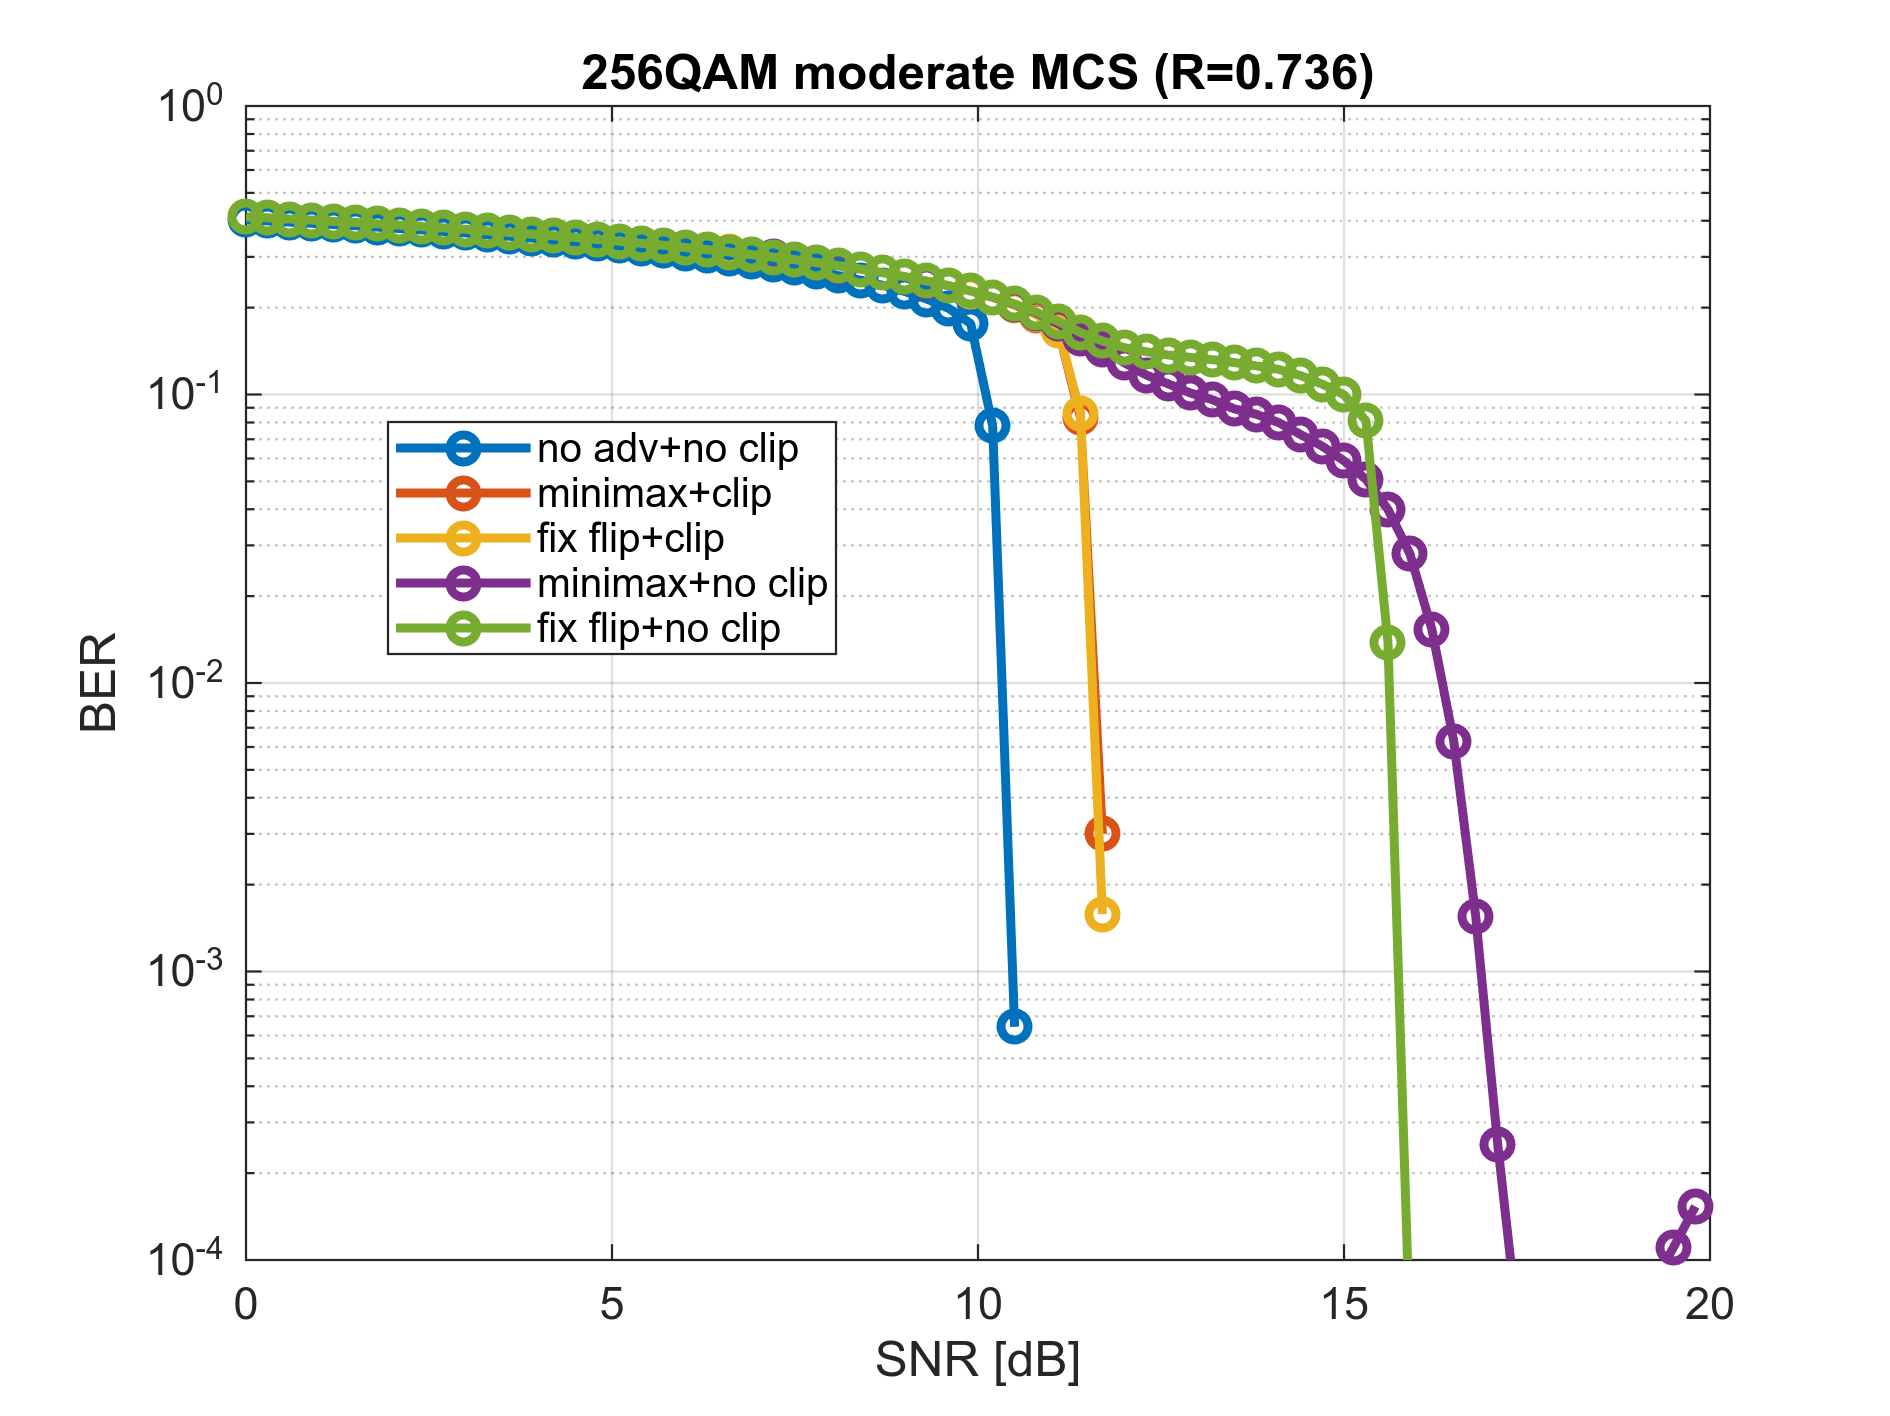


% Plotting
figure(1);
semilogy(SNRdB, BERavg, 'o-', 'linewidth', 2);
legend(methStr, 'Location', 'best');
grid on;
ylim([1e-4,1]);
ylabel('BER');
xlabel('SNR [dB]');
title(sprintf('%s %s MCS (R=%.3f)', modulation, mcsType, coderate));

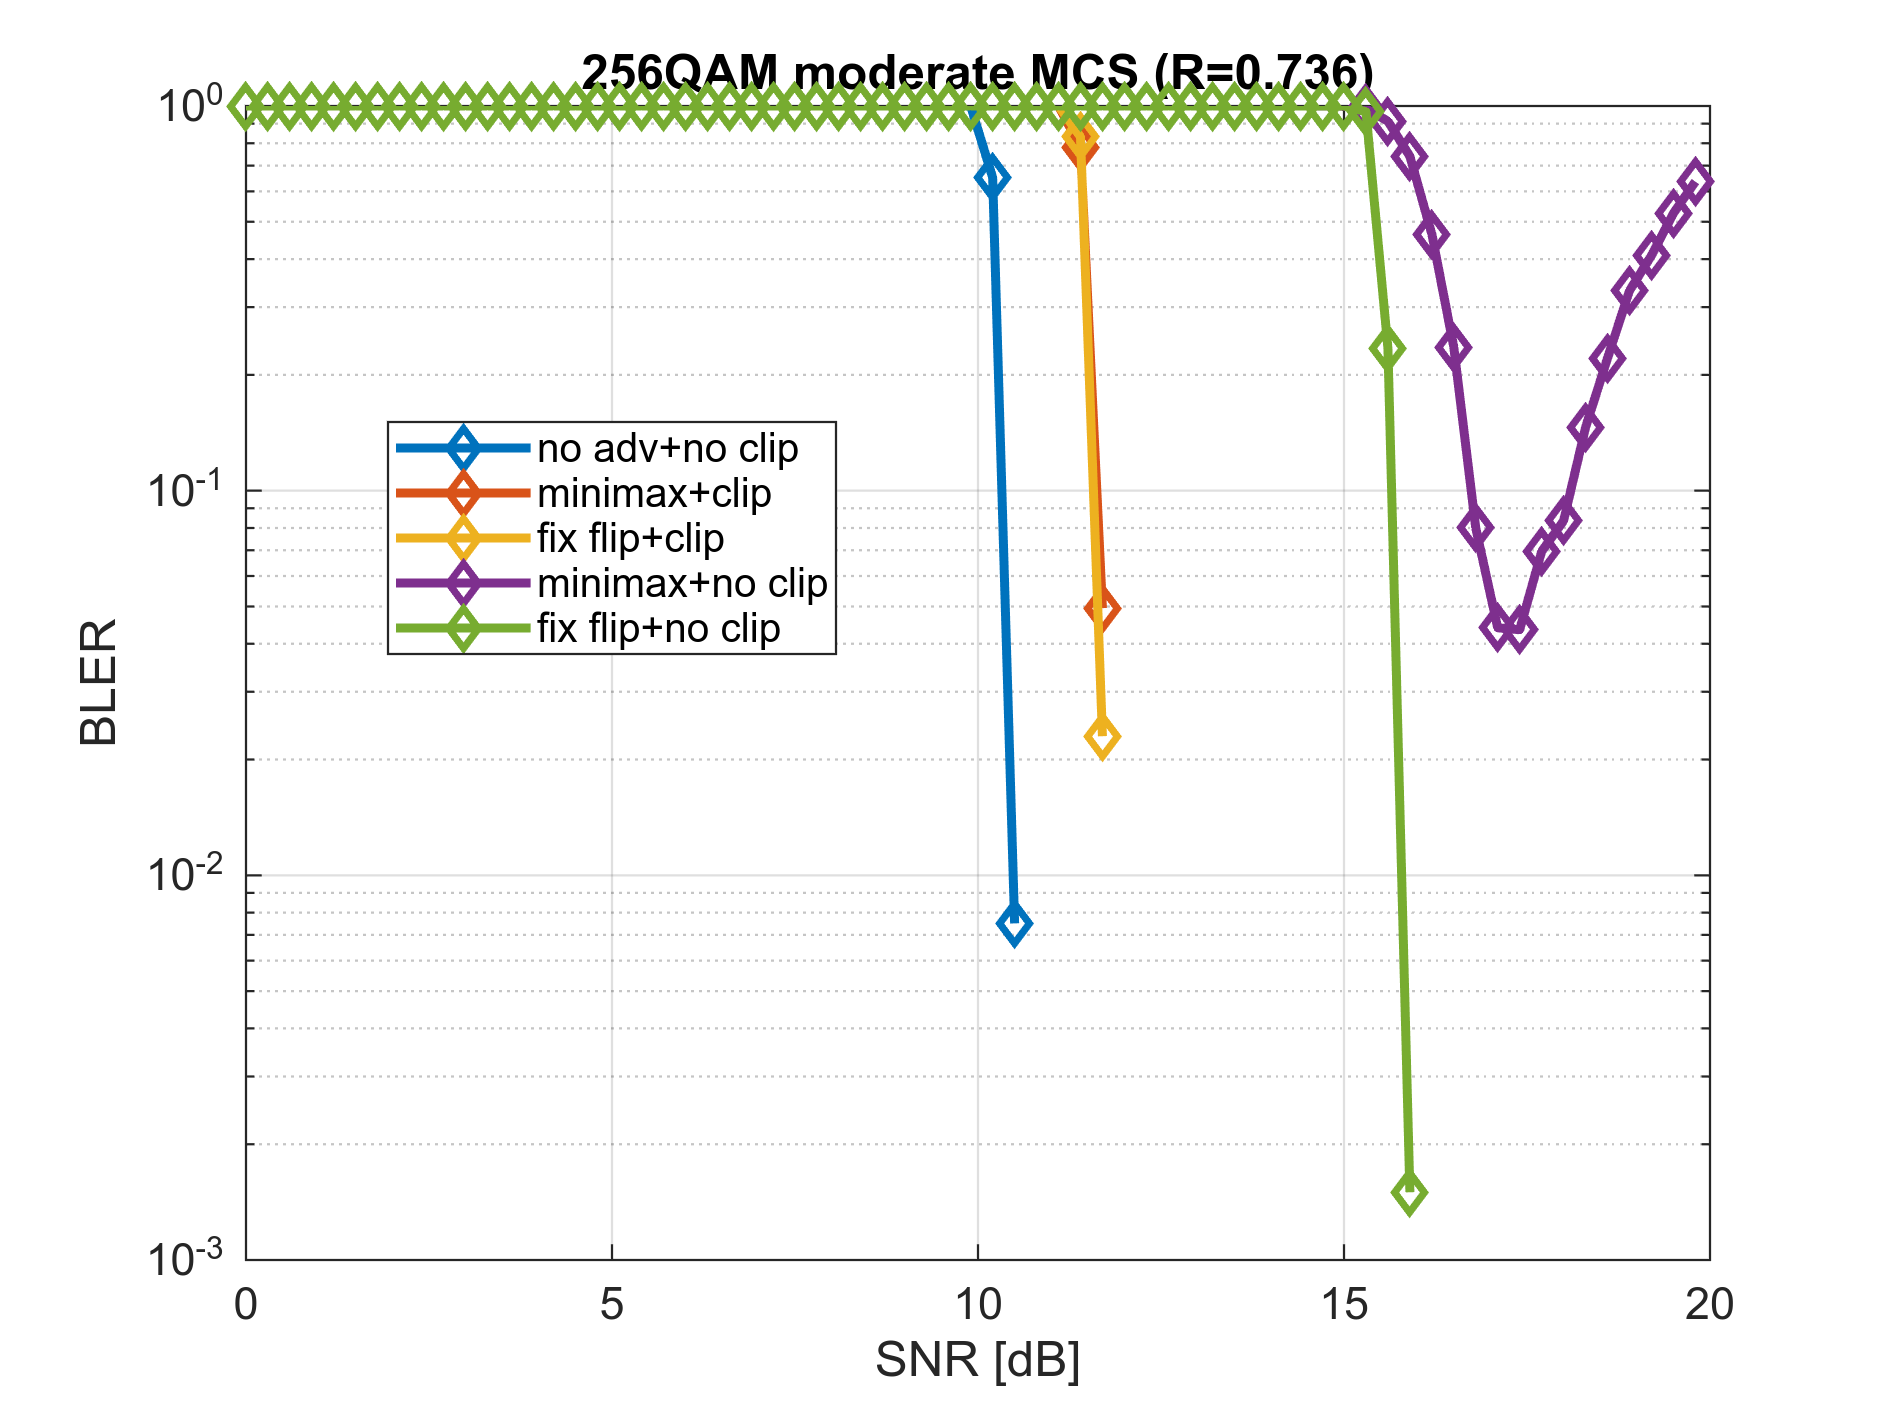


figure(2);
semilogy(SNRdB, BLERavg, 'd-', 'linewidth', 2);
legend(methStr, 'Location', 'best');hw3
grid on;
ylim([1e-3,1]);
ylabel('BLER');
xlabel('SNR [dB]');
title(sprintf('%s %s MCS (R=%.3f)', modulation, mcsType, coderate));